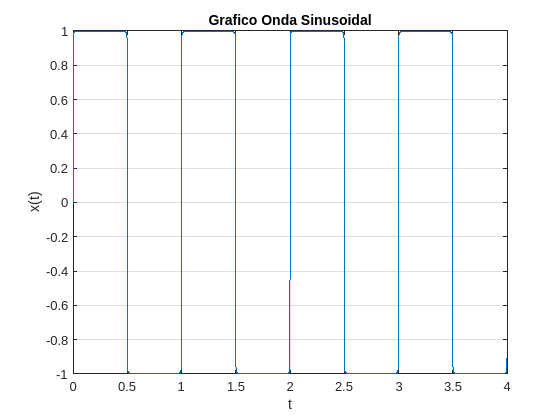

fo = 1;
k= 1000;
Fa = 1000;

a = zeros(1, k+1);

b = zeros(1, k+1);
ind = 1:2:k;
b(2:2:end) = 4./(ind*pi);

[sinal, t] = SomaFourier (1/Fa, fo, 4, a, b);

plot(t, sinal);

xlabel('t');
ylabel('x(t)');
title("Grafico Onda Sinusoidal");
grid on;

function [x, t] = SomaFourier(Ta, fo, Np, a, b)

    To = 1 / fo;
    t = 0 : Ta : Np * To - Ta;
    x= zeros(1, length(t));
    for k = 1 : length(a)
        x = x + a(k) * cos(2 * pi * (k-1) * fo * t) + b(k) * sin(2 * pi * (k - 1) * fo * t);
    end

end